Definindo Constantes

clear all
m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z

m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

Coeficiente de arrasto hidrodinâmicos

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

Velocidades de equilíbrio

U = 0.5;
V = 0.5;
R = 0.126;

Construções das matrizes linearizadas

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), 0, ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), 0, -((abs(U)*m_u)/m_v);
    0, 0, 0, 1;
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), 0, -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];
    

B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r;
     0, 0, 0];


C = eye(4,4);

D = zeros(4,3);

Criação do espaço de estados

sl = ss(A, B, C, D);

Determinando a função de transferência

[h1,y] = ss2tf(A, B, C, D, 1);

y1 = [y(1,1), y(1,2), y(1,3), y(1,4), 0];

tf11 = tf([h1(1,1), h1(1,2), h1(1,3), h1(1,4), h1(1,5)], y1);
tf12 = tf([h1(2,1), h1(2,2), h1(2,3), h1(2,4), h1(2,5)], y1);
tf13 = tf([h1(3,1), h1(3,2), h1(3,3), h1(3,4), h1(3,5)], y1);
tf14 = tf([h1(4,1), h1(4,2), h1(4,3), h1(4,4), h1(4,5)], y1);

[h2] = ss2tf(A, B, C, D, 2);

tf21 = tf([h2(1,1), h2(1,2), h2(1,3), h2(1,4), h2(1,5)], y1);
tf22 = tf([h2(2,1), h2(2,2), h2(2,3), h2(2,4), h2(2,5)], y1);
tf23 = tf([h2(3,1), h2(3,2), h2(3,3), h2(3,4), h2(3,5)], y1);
tf24 = tf([h2(4,1), h2(4,2), h2(4,3), h2(4,4), h2(4,5)], y1);


[h3] = ss2tf(A, B, C, D, 3);

tf31 = tf([h3(1,1), h3(1,2), h3(1,3), h3(1,4), h3(1,5)], y1);
tf32 = tf([h3(2,1), h3(2,2), h3(2,3), h3(2,4), h3(2,5)], y1);
tf33 = tf([h3(3,1), h3(3,2), h3(3,3), h3(3,4), h3(3,5)], y1);
tf34 = tf([h3(4,1), h3(4,2), h3(4,3), h3(4,4), h3(4,5)], y1);


Plotando os polos do sistema

pzmap(sl)
grid on

Gráficos de BODE

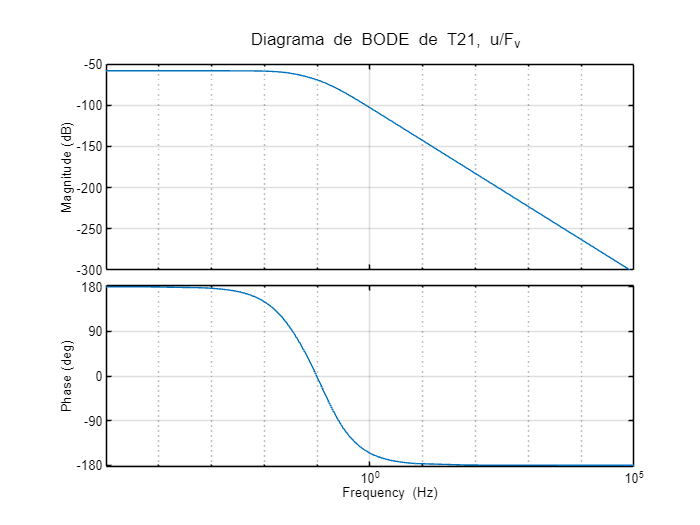

opts = bodeoptions;
opts.Title.FontSize = 10;
opts.FreqUnits = 'Hz';
opts.Xlim = ([1e-5, 1e5]);


bode(tf21, opts)
grid on
title 'Diagrama de BODE de T21, u/F_v '

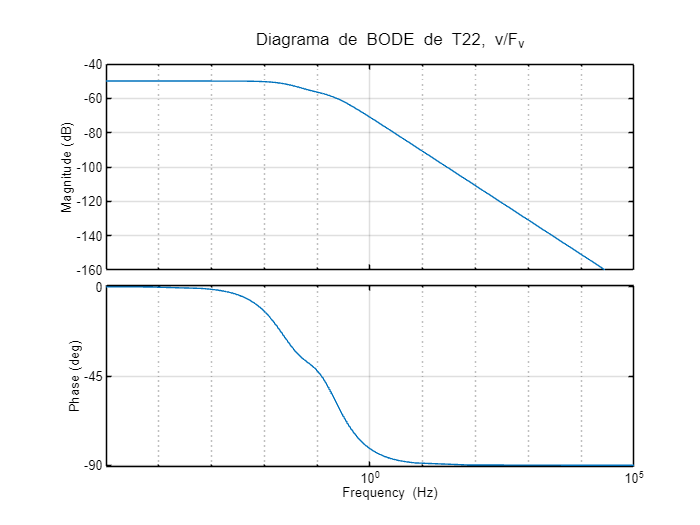


bode(tf22, opts)
grid on
title 'Diagrama de BODE de T22, v/F_v'

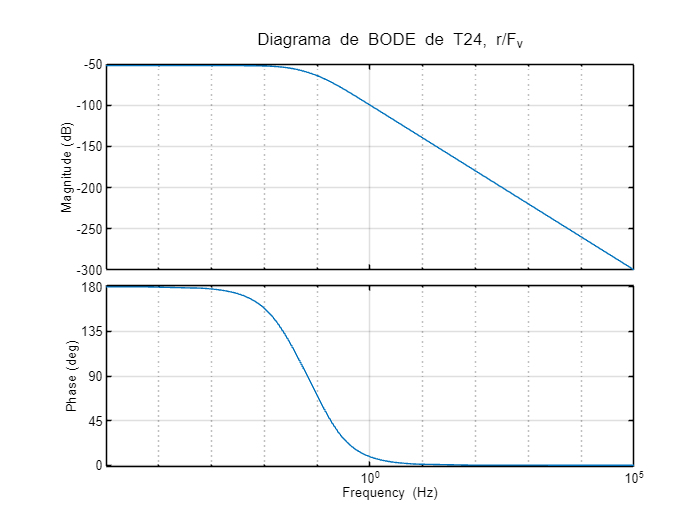


bode(tf24, opts)
grid on
title 'Diagrama de BODE de T24, r/F_v'

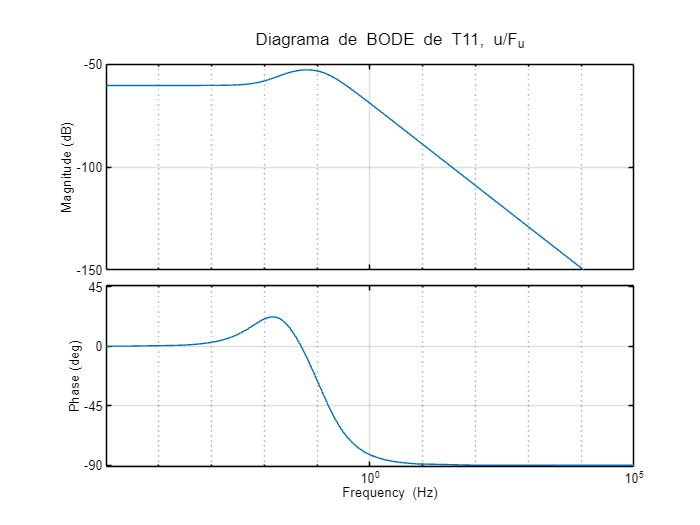


bode(tf11, opts);
grid on
title 'Diagrama de BODE de T11, u/F_u'

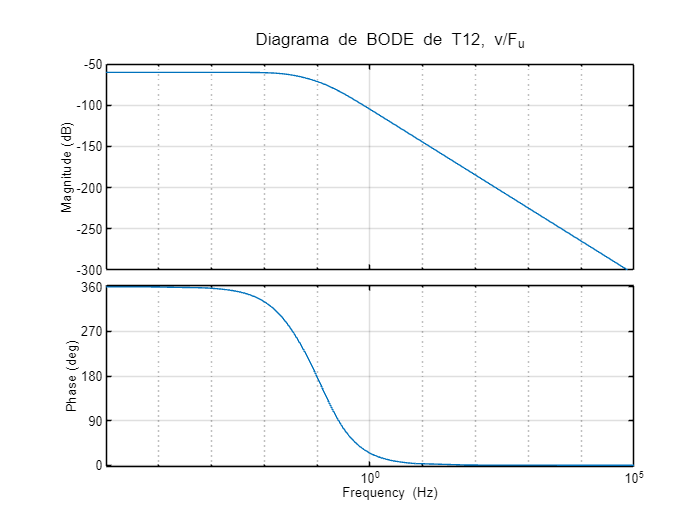


bode(tf12, opts);
grid on
title 'Diagrama de BODE de T12, v/F_u'

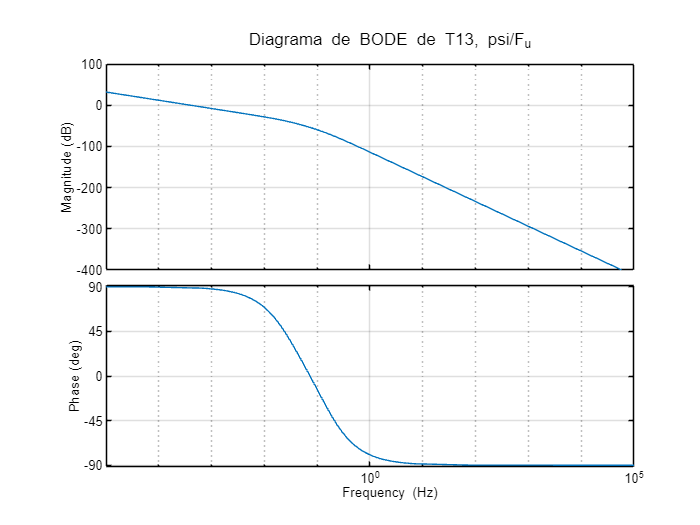


bode(tf13, opts);
grid on
title 'Diagrama de BODE de T13, psi/F_u'

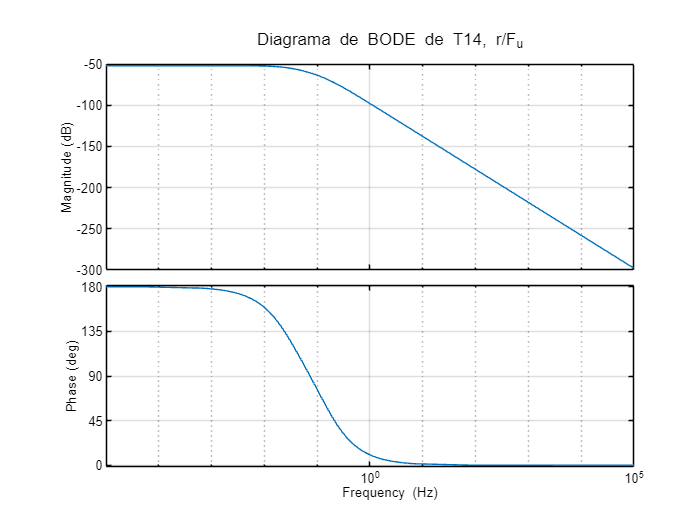


bode(tf14, opts)
grid on
title 'Diagrama de BODE de T14, r/F_u'

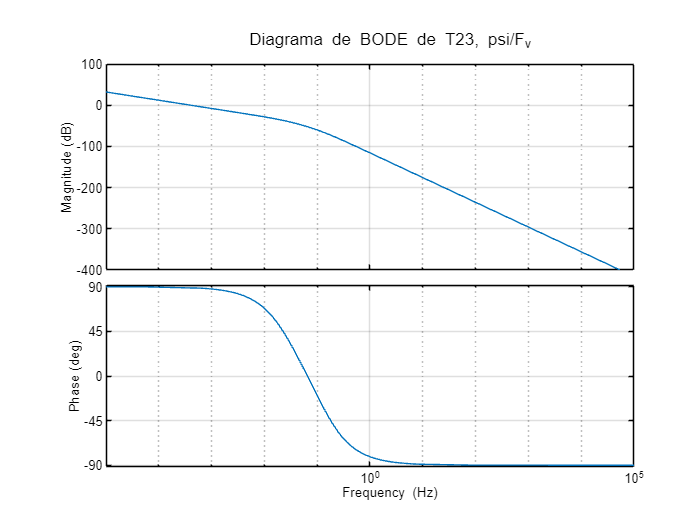



bode(tf23, opts)
grid on
title 'Diagrama de BODE de T23, psi/F_v'

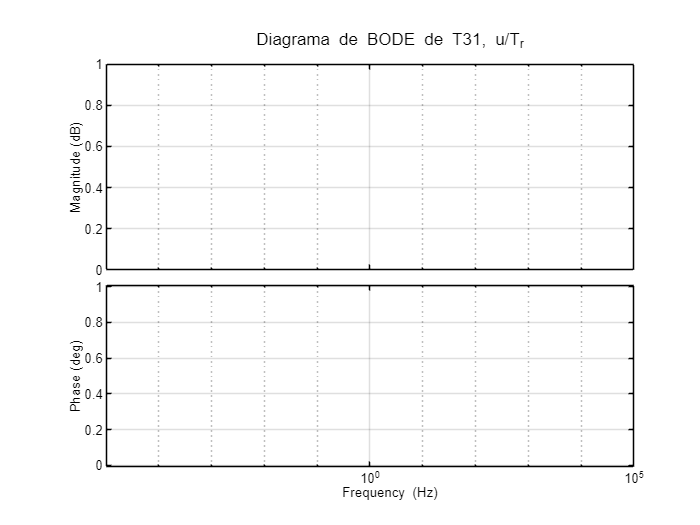


bode(tf31, opts)
grid on
title 'Diagrama de BODE de T31, u/T_r'

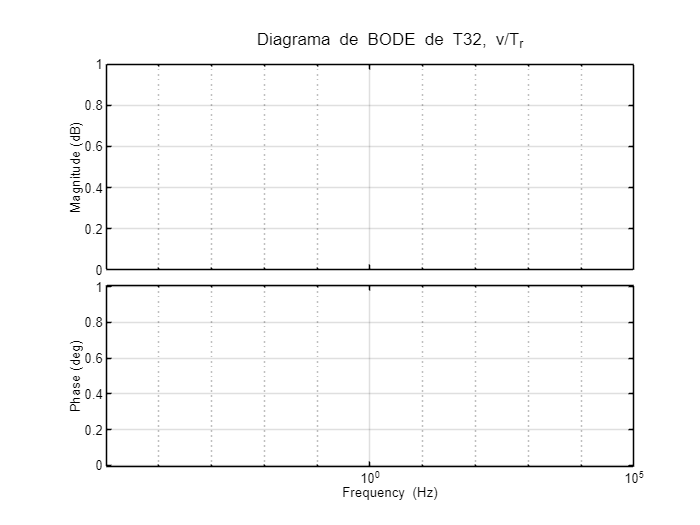


bode(tf32, opts)
grid on
title 'Diagrama de BODE de T32, v/T_r'

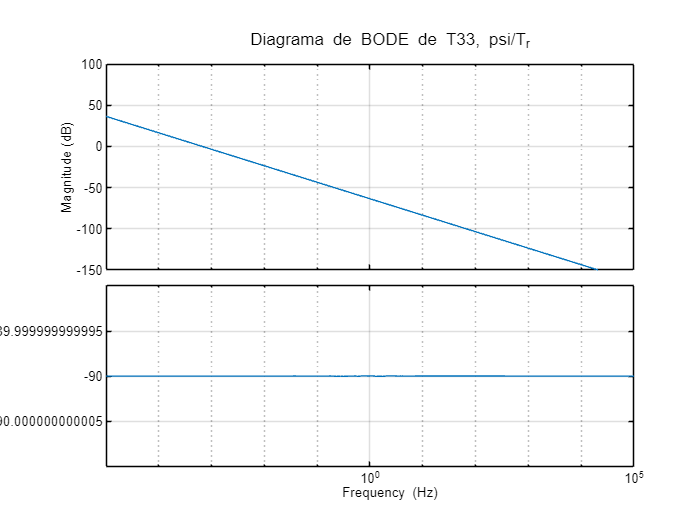


bode(tf33, opts)
grid on
title 'Diagrama de BODE de T33, psi/T_r'

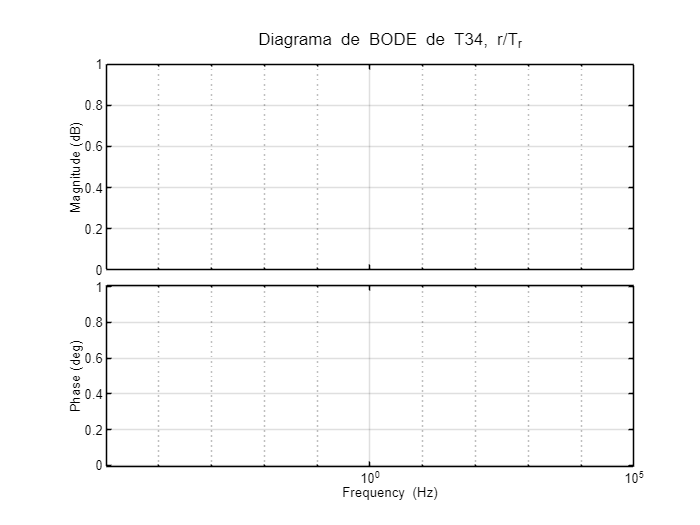


bode(tf34, opts)
grid on
title 'Diagrama de BODE de T34, r/T_r'